df = Scripps_Pier;

1. Visual evaluation. For both temperature and pressure, plot the records from the two years. Are there obvious discrepancies between the two years? What years are covered? Any other observations? 

- Years: 2006, 2016

- Discrepancies: In May of 2006 there are frequent drops in temperature. In June of 2016 there were similar frequent drops in temperature to those of 2006. In 2006 there was a rapid decrease in temperature follow by a rapid increase in temperature just prior to July.

- The two pressure records visually seem consistant with one another.

idx_2006 = find(df.datetime(:,1) == 2006);
idx_2016 = find(df.datetime(:,1) == 2016);

df.scripps_2006 = table(df.time(idx_2006),df.t(idx_2006),df.p(idx_2006));
vars = {'time','t','p'};
df.scripps_2006.Properties.VariableNames = vars;

df.scripps_2016 = table(df.time(idx_2016),df.t(idx_2016),df.p(idx_2016));
vars = {'time','t','p'};
df.scripps_2016.Properties.VariableNames = vars;

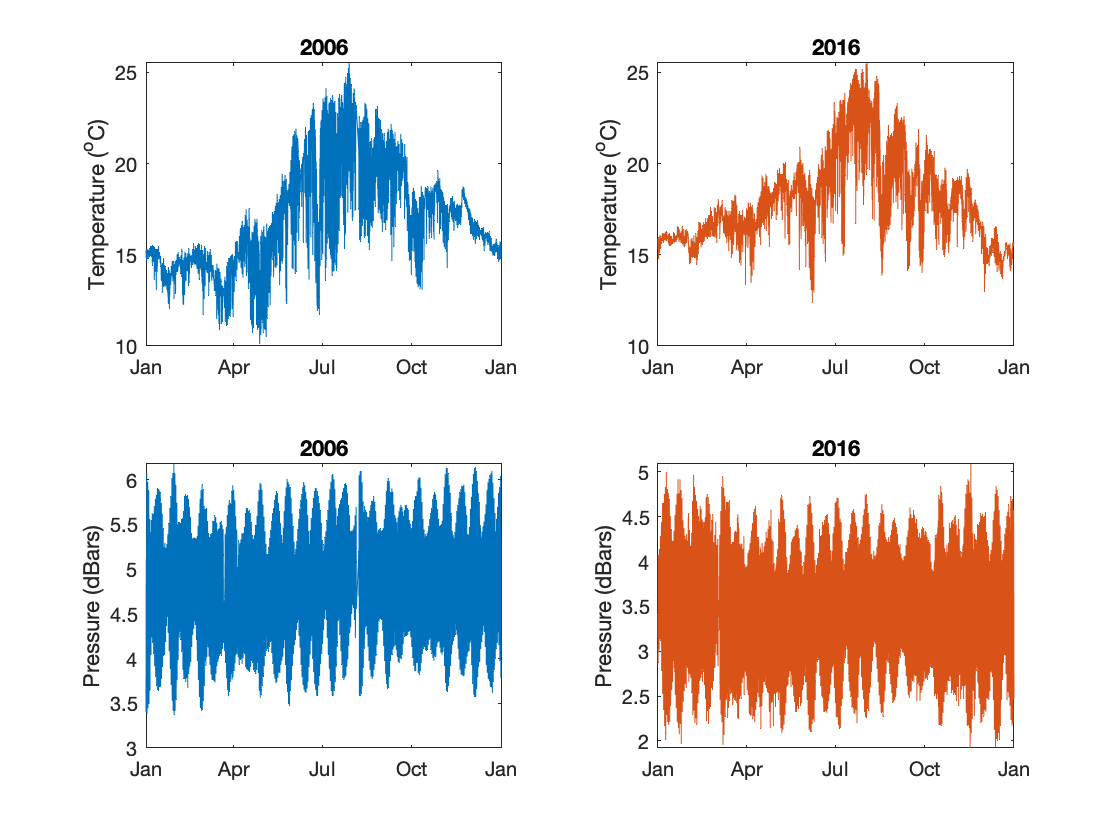

figure(1)
clf
tiledlayout(2,2)
nexttile
plot(df.scripps_2006.time,df.scripps_2006.t,'color','#0072BD')
datetick('x',3)
title('2006')
ylabel('Temperature (^oC)')
nexttile
plot(df.scripps_2016.time,df.scripps_2016.t,'color','#D95319')
datetick('x',3)
title('2016')
ylabel('Temperature (^oC)')


nexttile
plot(df.scripps_2006.time,df.scripps_2006.p,'color','#0072BD')
datetick('x',3)
title('2006')
ylabel('Pressure (dBars)')
nexttile
plot(df.scripps_2016.time,df.scripps_2016.p,'color','#D95319')
datetick('x',3)
title('2016')
ylabel('Pressure (dBars)')

2. Means. For each quantity, evaluate whether the sample mean between the two years is consistent within error bars. Do you obtain different results if you subsample the data at (say) once per day?

- Both years are not consistent within one standard error of the mean, however, they are consistent within one standard deviation.

- After subsampling, the standard error becomes much larger, however, it is still not enough to capture the means of both years.

- Eq: std error of mean: std dev / sqrt(N)								

3. Variance. For each quantity, evaluate whether the variance from the two years are consistent. Do you obtain different results if you subsample the data at (say) once per day? 

- The variance for both temperature and pressure are not consistent within error bars.

- For the subsampled data, however, both temperature and pressure are consistent within error bars.

- Eq: std error of variance: (std^2)*sqrt(2/(N-1))

t_2006 = stats(df.scripps_2006,'t');
t_2016 = stats(df.scripps_2016,'t');
p_2006 = stats(df.scripps_2006,'p');
p_2016 = stats(df.scripps_2016,'p');
stat = table(t_2006', t_2016',p_2006',p_2016');
stat.Properties.RowNames = {'mean', 'std', 'std_error', 'var', 'std_var'};
stat.Properties.VariableNames = {'2006t', '2016t', '2006p', '2016p'}

stat = 5×4 table
                   2006t        2016t        2006p        2016p  
                 _________    _________    _________    _________

    mean             17.04       18.253       4.8323       3.4587
    std             2.7947        2.512      0.50908      0.49406
    std_error    0.0079342    0.0081838    0.0014453    0.0016096
    var             7.8102       6.3099      0.25917      0.24409
    std_var       0.031358     0.029073    0.0010406    0.0011247


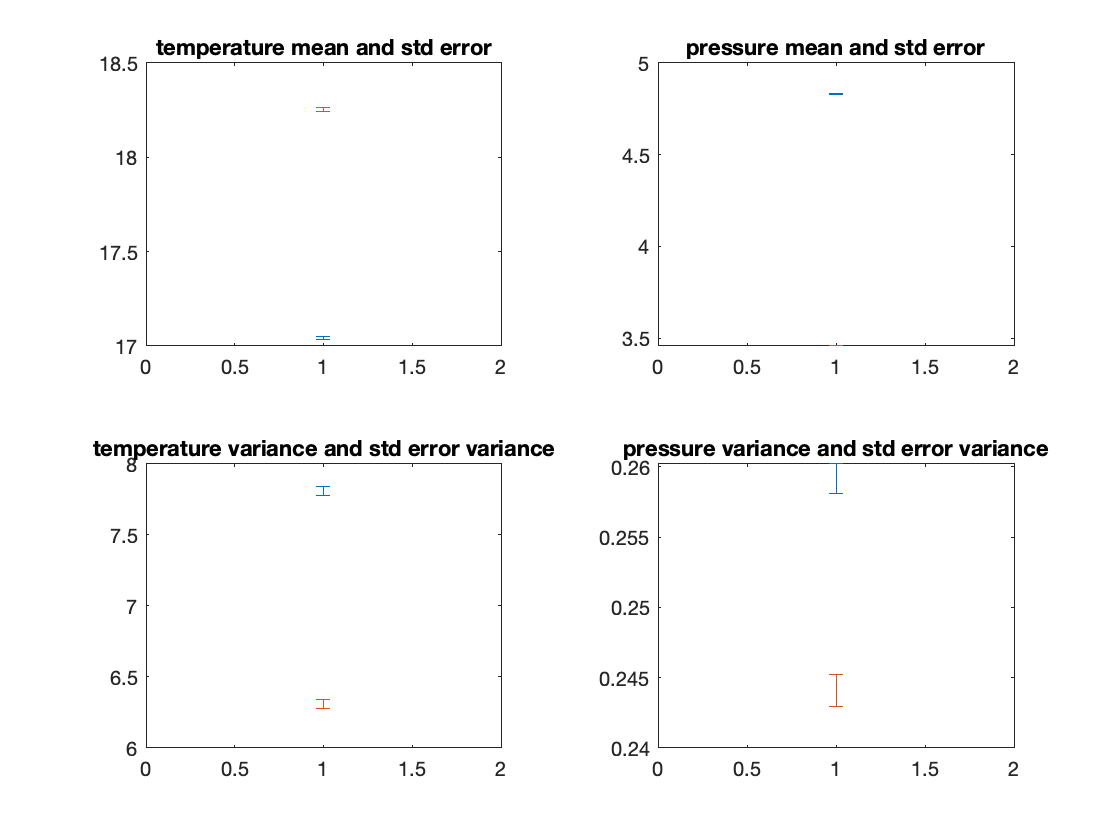


figure(2)
clf
tiledlayout('flow')

nexttile
errorbar(1,t_2006(1),t_2006(3)) % 1 is mean 3 is std error
hold on
errorbar(1,t_2016(1),t_2016(3))
title('temperature mean and std error')

nexttile
errorbar(1,p_2006(1),p_2006(3))
hold on
errorbar(1,p_2016(1),p_2016(3))
title('pressure mean and std error')

nexttile
errorbar(1,t_2006(4),t_2006(5))
hold on
errorbar(1,t_2016(4),t_2016(5))
title('temperature variance and std error variance')

nexttile
errorbar(1,p_2006(4),p_2006(5))
hold on
errorbar(1,p_2016(4),p_2016(5))
title('pressure variance and std error variance')

%subsample
%one record every 4 minutes. 360 records every day. grab one sample every
%day
df.scripps_2006_subsample = df.scripps_2006(1:360:end,:);
df.scripps_2016_subsample = df.scripps_2016(1:360:end,:);
t_2006 = stats(df.scripps_2006_subsample,'t');
t_2016 = stats(df.scripps_2016_subsample,'t');
p_2006 = stats(df.scripps_2006_subsample,'p');
p_2016 = stats(df.scripps_2016_subsample,'p');
stat_sub = table(t_2006', t_2016',p_2006',p_2016');
stat_sub.Properties.RowNames = {'mean', 'std', 'std_error', 'var', 'std_var'};
stat_sub.Properties.VariableNames = {'2006t', '2016t', '2006p', '2016p'}

stat_sub = 5×4 table
                  2006t      2016t      2006p       2016p  
                 _______    _______    ________    ________

    mean          17.098     18.354      4.8675      3.4727
    std           2.8625     2.6577     0.49958     0.50153
    std_error    0.15411    0.16419    0.026896    0.030985
    var           8.1938     7.0634     0.24958     0.25154
    std_var      0.62477    0.61832     0.01903    0.022019


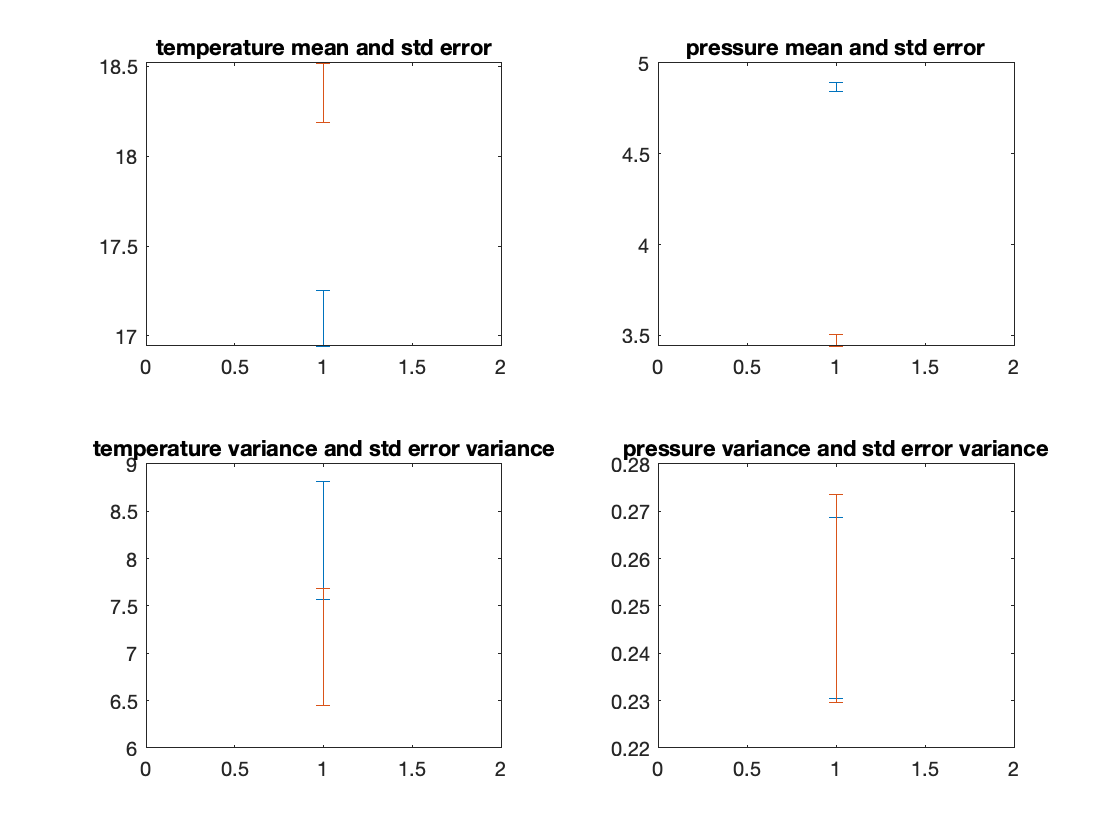


figure(3)
clf
tiledlayout('flow')

nexttile
errorbar(1,t_2006(1),t_2006(3))
hold on
errorbar(1,t_2016(1),t_2016(3))
title('temperature mean and std error')

nexttile
errorbar(1,p_2006(1),p_2006(3))
hold on
errorbar(1,p_2016(1),p_2016(3))
title('pressure mean and std error')

nexttile
errorbar(1,t_2006(4),t_2006(5))
hold on
errorbar(1,t_2016(4),t_2016(5))
title('temperature variance and std error variance')

nexttile
errorbar(1,p_2006(4),p_2006(5))
hold on
errorbar(1,p_2016(4),p_2016(5))
title('pressure variance and std error variance')

4. Extreme values. For each of the two years, compute the likelihood given the observed PDF, and a Gaussian PDF with the observed variance, of a temperature extreme value 2σ greater than the mean. 

- In 2006, the liklihood of a temperature extreme greater than 2σ was 0.025 or 2.5%

- in 2016, the liklihood of a temperature extreme greater than 2σ was 0.048 or 4.8%. In 2016, the chance of a low temperature exteme was much less than in 2006.

- In a gaussian distribution, the chance of a 2σ event should be 5%.

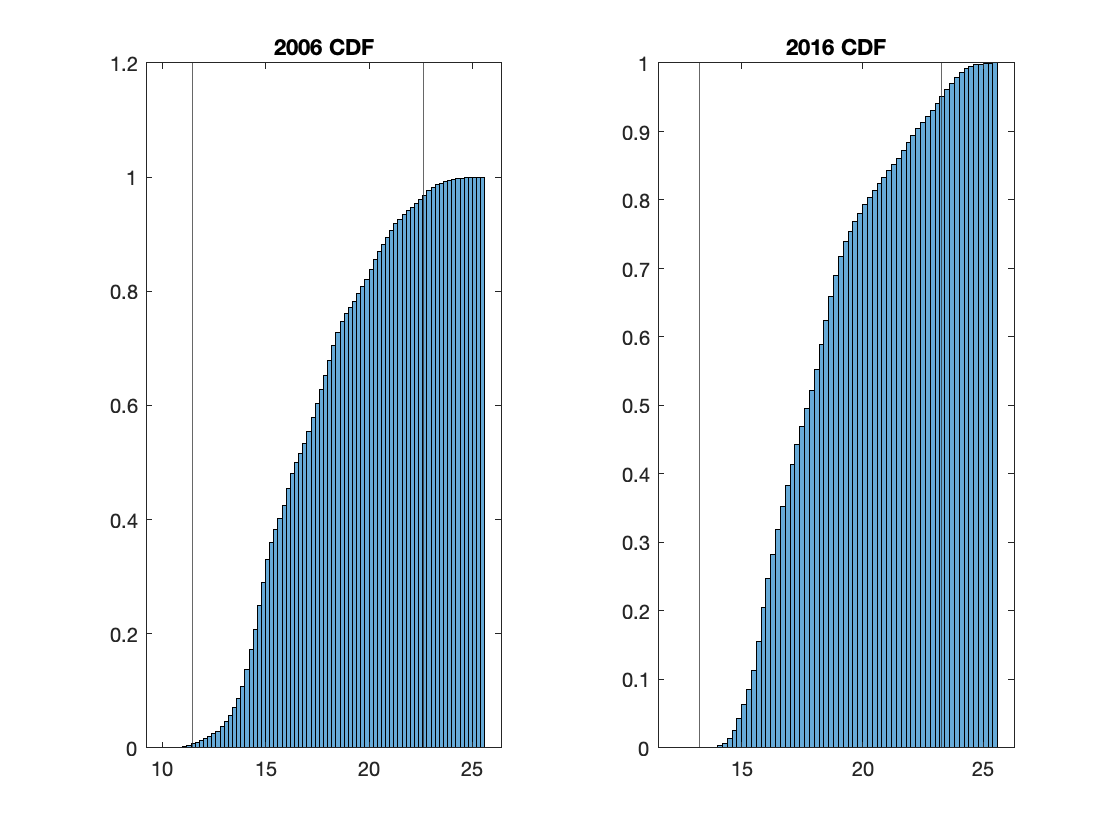

figure(4)
clf
tiledlayout(1,2)
nexttile
histogram(df.scripps_2006.t,"Normalization","cdf")
upper = 2*std(df.scripps_2006.t) + mean(df.scripps_2006.t);
lower =  -2*std(df.scripps_2006.t) + mean(df.scripps_2006.t);
extremes = find(df.scripps_2006.t >= upper & df.scripps_2006.t >= lower);
hold on
xline(upper)
xline(lower)
title('2006 CDF')
%1 - (0.968 + 0.007) = 0.025


nexttile
histogram(df.scripps_2016.t,"Normalization","cdf")
upper = 2*std(df.scripps_2016.t) + mean(df.scripps_2016.t);
lower =  -2*std(df.scripps_2016.t) + mean(df.scripps_2016.t);
extremes = find(df.scripps_2016.t >= upper & df.scripps_2016.t >= lower);
hold on
xline(upper)
xline(lower)
title('2016 CDF')

%1- (0.952 + 0.0006) = 0.048

5. Probability density functions. For both pressure and temperature, plot the pdfs for the two years on the same axes. Overplot the Gaussian and uniform distributions that have the observed mean and variance. 

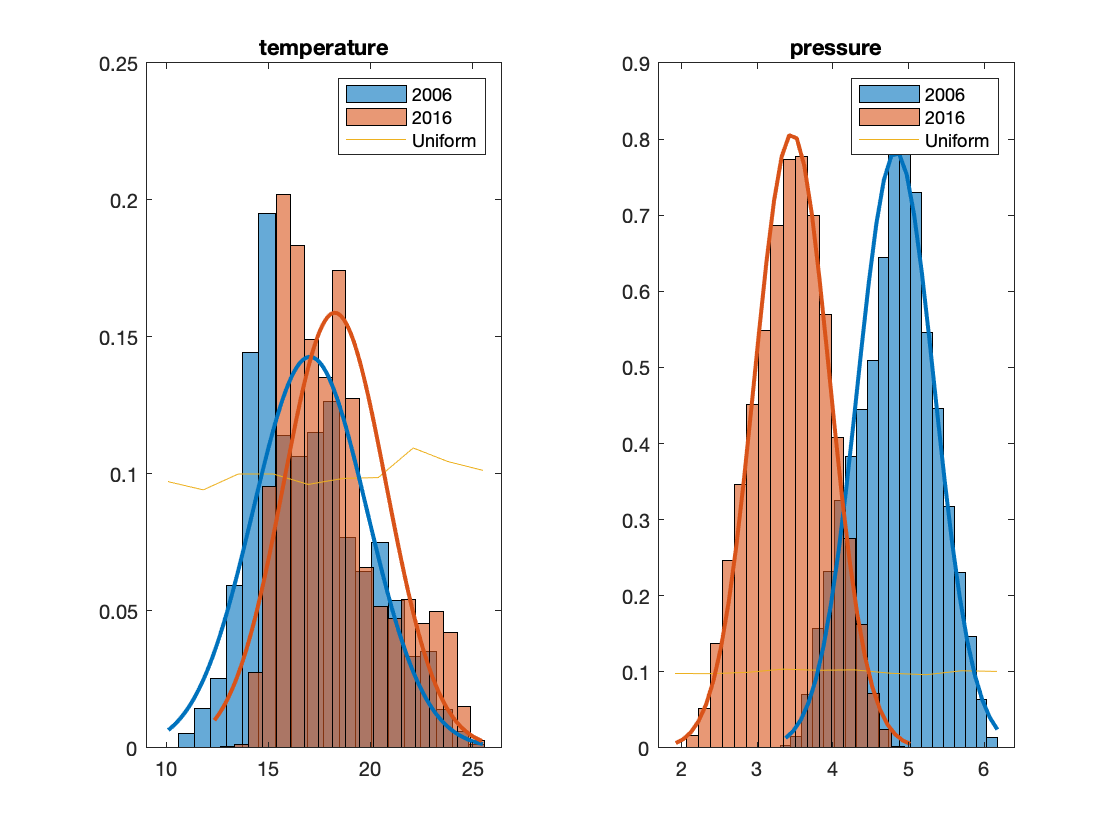

figure(5)
clf
tiledlayout(1,2)

nexttile
histogram(df.scripps_2006.t,"Normalization","pdf","FaceColor",'#0072BD',"NumBins",20)
hold on
histogram(df.scripps_2016.t,"Normalization","pdf","FaceColor",'#D95319',"NumBins",20)

%Uniform
x = linspace(min(df.scripps_2006.t),max(df.scripps_2006.t),10);
r = rand(10000,1)*std(df.scripps_2006.t) + mean(df.scripps_2006.t);
[c1 c2] = hist(r,10);
c1pdf=c1./sum(c1);
plot(x,c1pdf)

%Gaussian
x = (min(df.scripps_2006.t):.1:max(df.scripps_2006.t));
norm = normpdf(x,mean(df.scripps_2006.t),std(df.scripps_2006.t));
plot(x,norm,"LineWidth",2,'Color','#0072BD')

x = (min(df.scripps_2016.t):.1:max(df.scripps_2016.t));
norm = normpdf(x,mean(df.scripps_2016.t),std(df.scripps_2016.t));
plot(x,norm,"LineWidth",2,'Color','#D95319')


title('temperature')
legend('2006', '2016', 'Uniform')


nexttile
histogram(df.scripps_2006.p,"Normalization","pdf","FaceColor",'#0072BD',"NumBins",20)
hold on
histogram(df.scripps_2016.p,"Normalization","pdf","FaceColor",'#D95319',"NumBins",20)

%Uniform
x = linspace(min(df.scripps_2016.p),max(df.scripps_2006.p),10);
r = rand(10000,1)*std(df.scripps_2006.p) + mean(df.scripps_2006.p);
[c1 c2] = hist(r,10);
c1pdf=c1./sum(c1);
plot(x,c1pdf)

%Gaussian
x = (min(df.scripps_2006.p):.1:max(df.scripps_2006.p));
norm = normpdf(x,mean(df.scripps_2006.p),std(df.scripps_2006.p));
plot(x,norm,"LineWidth",2,'Color','#0072BD')

x = (min(df.scripps_2016.p):.1:max(df.scripps_2016.p));
norm = normpdf(x,mean(df.scripps_2016.p),std(df.scripps_2016.p));
plot(x,norm,"LineWidth",2,'Color','#D95319')

title('pressure')
legend('2006', '2016','Uniform')

6. Variance reduction by averaging. As a bonus, can you demonstrate that the sample variance of N-sample averages decreases as N as we learned in class? 

- It is clear that the error of variance decreases significantly with the number of results from the table below. In 2006 and 2016, N is around 100,000, whereas N for t_all is about 2 million. 

df.scripps_all = table(df.time,df.t,df.p);
vars = {'time','t','p'};
df.scripps_all.Properties.VariableNames = vars;
t_2006 = stats(df.scripps_2006,'t');
t_2016 = stats(df.scripps_2016,'t');
t_all = stats(df.scripps_all,'t');
stat = table(t_2006', t_2016',t_all');
stat.Properties.RowNames = {'mean', 'std', 'std_error', 'var', 'std_var'};
stat.Properties.VariableNames = {'2006t', '2016t','all_t'}

stat = 5×3 table
                   2006t        2016t        all_t  
                 _________    _________    _________

    mean             17.04       18.253       17.809
    std             2.7947        2.512        2.751
    std_error    0.0079342    0.0081838    0.0019998
    var             7.8102       6.3099       7.5679
    std_var       0.031358     0.029073      0.00778


Check for missing argument or incorrect argument data type in call to function 'export'.